**Connor- Stevens model**

Key reference: Connor JA, Stevens CF. Prediction of repetitive firing behaviour from voltage

clamp data on an isolated neurone soma. J Physiol. 1971 Feb;213(1):31-53. doi:

10.1113/jphysiol.1971.sp009366. PMID: 5575343; PMCID: PMC1331721.

The Connor- Stevens model is similar to the Hodgkin-Huxley model, but also

incorporates a transient K conductance called the A current. this current slows the

upstroke of the action potential and leads to greater stability of neuronal firing- for the

Connor Stevens neuron, firing rate rises steadily as a function of input current (type I),

unlike the HH neuron (type 2).

The equations for the total current, A conductance and transition rates are

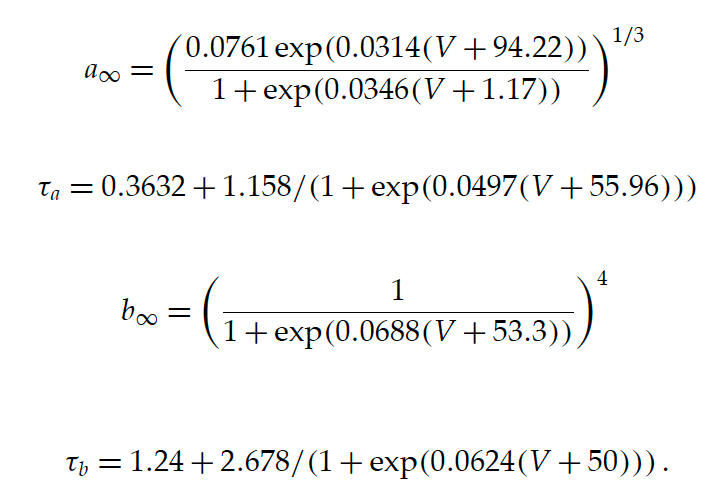

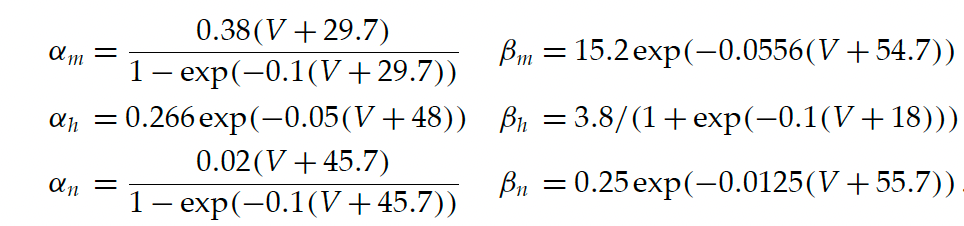

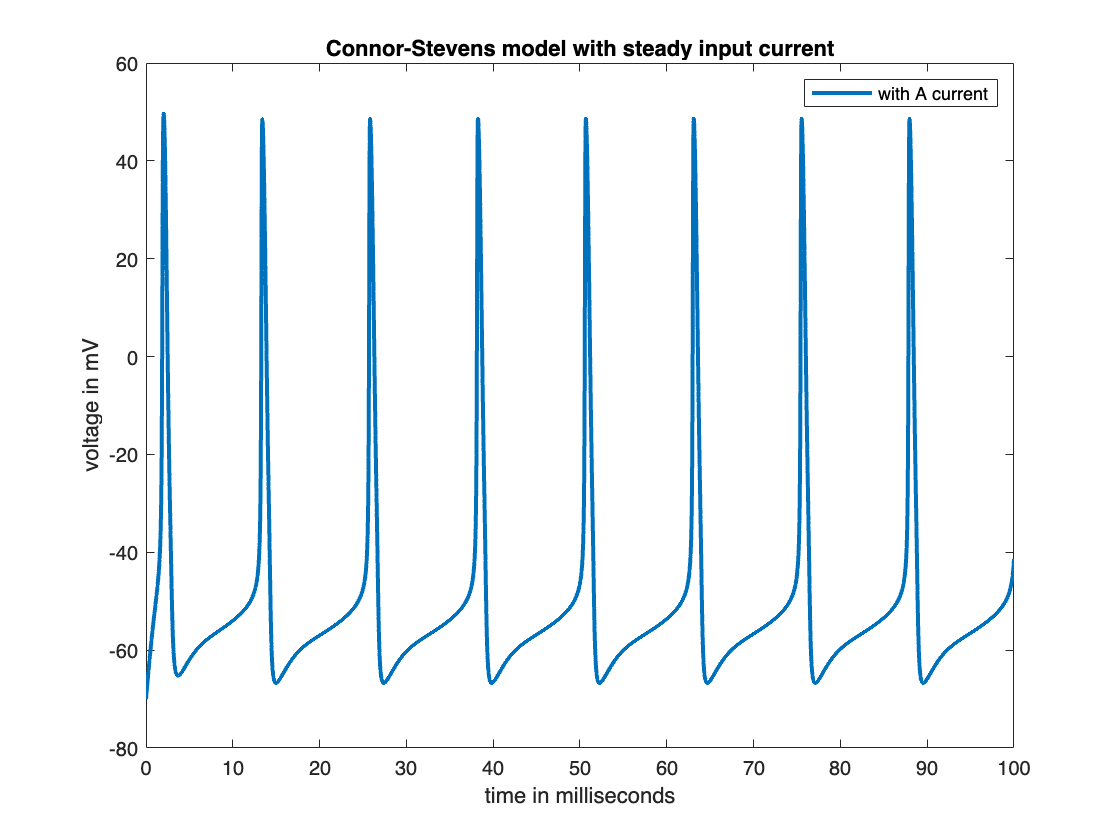

maxt= 100;
delta_t= 0.01;
t= 0:delta_t:maxt;
external_current= 5;
%constant parameters
% conductance units in mS/cm^2
gbar_K= 20;
gbar_Na= 120;
gbar_A= 47.7;
g_L= 0.3;
Cap= 1;
A=1; %surface area of the cell in cm^2
%voltage units in mV
E_K= -72;
E_Na= 55;
E_L= -17;
E_A= -75;
V=-70; %initial resting membrane potential
%initialize transition rates for m, n and h gating variables
alpha_m= zeros(size(t));
beta_m= zeros(size(t));
alpha_n= zeros(size(t));
beta_n= zeros(size(t));
alpha_h= zeros(size(t));
beta_h= zeros(size(t));
% initialize open probabilities
n = zeros(size(t));
m = zeros(size(t));
h = zeros(size(t));
a = zeros(size(t));
b = zeros(size(t));
for i=1:length(t)-1
%calculate the coefficients
%Equations here are same as above, just calculating at each time step
alpha_m(i) = .38* (V(i)+29.7) / (1- exp(-(V(i)+29.7)/10)) ;
beta_n(i) = 0.25*exp(-(V(i)+55.7)/80);
alpha_n(i)= .02*(V(i)+45.7) / (1-exp(-(V(i)+45.7)/10));
beta_m(i) = 15.2*exp(-(V(i)+54.7)/18);
alpha_h(i) = .266*exp(-(V(i)+48)/20);
beta_h(i) = 3.8/(1+ exp(-(V(i)+18)/10));
% steady-state open probabilities
n_inf= alpha_n(i)/(alpha_n(i)+ beta_n(i));
m_inf= alpha_m(i)/(alpha_m(i)+beta_m(i));
h_inf= alpha_h(i)/(alpha_h(i)+beta_h(i));
%extra open probabilities of the transient K+ conductance introduced
%by the model
a_inf= ((0.0761*exp(0.0314*(V(i)+94.22)))/(1+exp(0.0497*(V(i)+55.96))))^(1/3);
b_inf= (1+exp(0.0688*(V(i)+53.3)))^(-4);
%calculate time constants
tau_n= 1/(alpha_n(i)+beta_n(i));
tau_m= 1/(alpha_m(i)+beta_m(i));
tau_h= 1/(alpha_h(i)+beta_h(i));
% time constants for the transient K+ conductance
tau_a= 0.3632+ (1.158/(1+exp(0.0497*(V(i)+55.96))));
tau_b= 1.24+(2.687/(1+exp(0.0624*(V(i)+50))));
%update open probabilities using exponential Euler
n(i+1) = n_inf+(n(i)-n_inf)*exp(-delta_t/tau_n);
m(i+1) = m_inf+(m(i)-m_inf)*exp(-delta_t/tau_m);
h(i+1) = h_inf+(h(i)-h_inf)*exp(-delta_t/tau_h);
a(i+1) = a_inf+(a(i)-a_inf)*exp(-delta_t/tau_a);
b(i+1) = b_inf+(b(i)-b_inf)*exp(-delta_t/tau_b);
%calculate the conductances and currents
g_Na= (m(i+1)^3) * gbar_Na * h(i+1);
I_Na = g_Na * (V(i)-E_Na);
g_K = (n(i+1)^4) * gbar_K;
I_K= g_K *(V(i)-E_K);
I_L = g_L *(V(i)-E_L);
%for transient K+ current
g_A= gbar_A * (a(i+1)^3) *b(i+1);
I_A= g_A* (V(i)-E_A);
%compute total ionic current
I_ion = external_current -(I_K + I_Na + I_L+I_A) ;
g= g_Na +g_K+g_L+g_A; % total conductance is the sum of the parallel conductances
gE= g_Na*E_Na + g_L*E_L + g_K*E_K +g_A*E_A;
%variable external current
% external_current(i+1) = external_current(i)+0.01;
V_inf = (gE+ external_current/A) / g; % steady-state voltage
% update tau_V
tau_V = Cap/g;
% update membrane potential using exponential Euler
V(i+1) = V_inf + (V(i)-V_inf)*exp(-delta_t/tau_V);
end
%can exclude the A term throughout to get the basic Hodgkin-Huxley model
%without the A current 
plot(t, V, LineWidth=2);
hold on
xlabel('time in milliseconds')
ylabel('voltage in mV');
title('Connor-Stevens model with steady input current');
legend('with A current');